# Test Mappings

clear vars; close all; clc;
warning('off','all')

% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
rdof = hSSMDim; odof = rdof;
load dataDecayObs

## Visualize Training Data

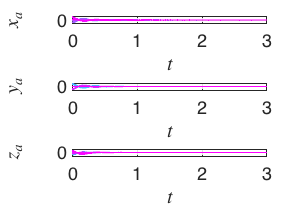

trajs = [1, 2, 3];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
Ts = 1/(tipData{iTraj,1}(2)-tipData{iTraj,1}(1));
freqHz = 15;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}(trajs,:);%transpose(lowpass(transpose(oData{iTraj,2}(trajs,:)), freqHz, Ts));
end

Visualize filtered data

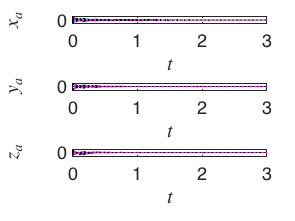

trajs = [1, 2, 3];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
        plot(tipData{iTraj,1},tipData{iTraj,2}(iObs,:), 'k:', 'Linewidth',1)
    end
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

overEmbed = 60;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 195 embedding coordinates consist of the 3 measured states and their 64 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);
oDataTrunc = sliceTrajectories(yData, sliceInt);

% Resample data to Ts = 0.01 to decrease size for PCA
% Process the data
Ts = 0.01;
sim_data = {};
sim_data.yData = yDataTrunc;
sim_data.oData = oDataTrunc;

resampled_data = data.resample(sim_data, Ts);
yDataTruncSumsample = resampled_data.yData;

PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


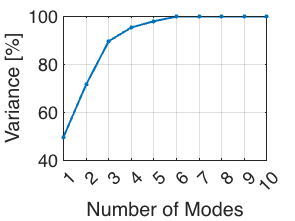

Xsnapshots = cat(2,yDataTruncSumsample{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
nTraj = size(oData,1);
indTest = [1 3 5 7 9 11 13 15];
indTrain = setdiff(1:nTraj,indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.0455

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.0432

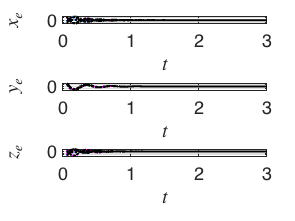


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.5514 +17.3790i
  -3.1060 +17.4358i
  -3.6217 +18.2395i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)

Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = Inf

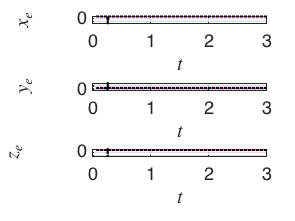

yRec = liftTrajectories(IMInfo, etaRec);

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

% Define custom chart only based on tip data and 1 delay
yDataTruncNew = yDataTrunc;
for iTraj = 1:size(yData,1)
    yDataTruncNew{iTraj,2} = yDataTrunc{iTraj,2}(end-5:end,:);
end

IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:),'style','custom');
tanSpace0_not_orth = IMInfo_paramonly.parametrization.tangentSpaceAtOrigin;
tanSpace0 = orthogonalizeGramSchmidt(tanSpace0_not_orth);
% Change coordinates
etaDataTruncNew = etaDataTrunc;
for iTraj = 1:size(etaDataTrunc,1)
    etaDataTruncNew{iTraj,2} = transpose(tanSpace0)*tanSpace0_not_orth*etaDataTrunc{iTraj,2};
end
% Fit new parametrization
IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTruncNew(indTrain,:),'Ve',tanSpace0,'style','custom');
disp('Results of new parametrization fit:')

Results of new parametrization fit:


yRec = liftTrajectories(IMInfo_paramonly, etaDataTruncNew);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.1041

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.1095


IMInfo_chartonly = IMGeometry(etaDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',yDataTruncNew(indTrain,:),'Ve',transpose(tanSpace0),'style','custom');
disp('Results of new chart fit:')

Results of new chart fit:


etaRec = liftTrajectories(IMInfo_chartonly, yDataTruncNew);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.1148

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.1182


% Define new IMInfo
IMInfo = struct('chart', IMInfo_chartonly.parametrization, 'parametrization', IMInfo_paramonly.parametrization);

% Define new RDInfo
ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTruncNew(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.5514 +17.3790i
  -3.1060 +17.4358i
  -3.6217 +18.2395i


Rauton = RDInfo.reducedDynamics.map;
disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:



etaRec = advectRD(RDInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 1.8911

yRec = liftTrajectories(IMInfo, etaRec);

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 1.8911

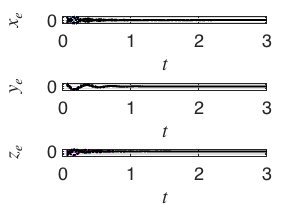

yRec = liftTrajectories(IMInfo, etaRec);
outdofsNew = [4 5 6];

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); indPlot = indTest; %indTrain(isinf(normedTrajDist(indTrain)) == 0);

labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt); colororder(cool(length(indPlot)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yDataTruncNew{indPlot(iTraj),1},yDataTruncNew{indPlot(iTraj),2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yRec{indPlot(iTraj),1},yRec{indPlot(iTraj),2}(outdofsNew(iObs),:),'k:','Linewidth',2)
    end
end

## Load controlled data

% Load and process tpwl data for tip coords only
load diamond_val_full
% load koopman_data_figureEight
y = y';
u = u';
y = y(4:end, :); % only tip displacements

zu = {};
%keptIdxs = 100:600;
keptIdxs = 1:size(y,2);
zu{1,1} = t(keptIdxs); zu{1,2} = y(:, keptIdxs) - y(:, end); uCell{1,1} = t(keptIdxs); uCell{1,2} = u(:, keptIdxs); Yu = zu; Udelay = uCell;
for iTraj = 1:size(Yu, 1)
    Yu{iTraj,1} = zu{iTraj,1}(2:end); 
    Yu{iTraj,2} = [zu{iTraj,2}(:,1:end-1); zu{iTraj,2}(:,2:end)]; 
    Udelay{iTraj,1} = uCell{iTraj,1}(2:end); 
    Udelay{iTraj,2} = uCell{iTraj,2}(:,2:end); 
end

% v then w mapping
% yDataRemapped = yDataInput;
% xData = yDataInput;
% for iTraj = 1:size(yDataInput, 1)
%     xData{iTraj, 2} = transpose(Vde) * yDataInput{iTraj, 2}; % Project down
%     yDataRemapped = liftTrajectories(IMInfo, xData); % Project up
%     % yDataRemapped{iTraj, 2} = Vde * xData{iTraj, 2}; % Project up with standard projection
% end

% Plot data
% customFigure('subPlot',[numCoord 1]);
% subplot(numCoord,1,1);
% for iPlt = 1:length(outdofs)
%     subplot(numCoord,1,iPlt);
%     xlabel('$t$','Interpreter','latex');
%     ylabel(labels(iPlt),'Interpreter','latex');
% end
% for iTraj = 1:length(size(yDataRemapped, 1))
%     for iObs = 1:length(outdofs)
%         subplot(numCoord,1,iObs);
%         plot(zu{iTraj,1},zu{iTraj,2}(iObs,:),'Linewidth',1)
%     end
% end
% % Plot control inputs
% customFigure;
% plot(uCell{1,1}, uCell{1,2},'Linewidth',1);
% xlabel('$t$','Interpreter','latex');
% ylabel('$\mathbf{u}$','Interpreter','latex');
% legend('$u_1$','$u_2$','$u_3$','$u_4$','location','NE','Interpreter','latex');

## Learn control matrix

From theory, we expect the following corrections in the reduced order model:


$$\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{r}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{r}}} \mathit{\mathbf{u}}\left(t\right)$$



$$\mathit{\mathbf{y}}=\mathit{\mathbf{v}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{v}}} \int_0^t \mathit{\mathbf{u}}\left(s\right)\textrm{ds}$$


under the assumptions that the control action is small and that the dynamics of other structural modes can be neglected.

% Setup trajectories for fit
% [Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);
% [Udelay, ~] = coordinatesEmbeddingControl(uCell, SSMDim, 'OverEmbedding', overEmbed, 'ndim', size([zu{1,2}], 1));

uFigureEight = readmatrix("../system_data/u_big.csv");
z = readmatrix("../system_data/z_big.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';

% Currently using big figure 8 trajectory
z_eight_true = z(4:end, :);
z_eight_shift = z_eight_true - z_eq.';
U_eight = uFigureEight.';

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1);

zu = {};
zu{1,1} = t_span; zu{1,2} = z_eight_shift; uCell{1,1} = t_span; uCell{1,2} = U_eight; Yu = zu; Udelay = uCell;
for iTraj = 1:size(Yu, 1)
    Yu{iTraj,1} = zu{iTraj,1}(2:end); 
    Yu{iTraj,2} = [zu{iTraj,2}(:,1:end-1); zu{iTraj,2}(:,2:end)]; 
    Udelay{iTraj,1} = uCell{iTraj,1}(2:end); 
    Udelay{iTraj,2} = uCell{iTraj,2}(:,2:end); 
end
yuxData = cell(size(Yu,1),4);
for iTraj = 1:size(Yu, 1)
   yuxData{iTraj,1} = Yu{iTraj,1};
   yuxData{iTraj,2} = Yu{iTraj,2};
   yuxData{iTraj,3} = Udelay{iTraj,2};
   yuxData{iTraj,4} = IMInfo.chart.map(Yu{iTraj,2});
end
% Fit control matrices
[Br,Bv,regErrors] = fitControlMatrices(yuxData,RDInfo,IMInfo)

Br =     0.0653   -0.0221   -0.0166   -0.0182
   -0.2572    0.3532   -0.3808    0.3191
   -0.0603    0.0851   -0.1201    0.1112
   -0.0041   -0.0021   -0.0014    0.0019
    0.0053   -0.0057    0.0009   -0.0014
   -0.0014   -0.0002    0.0002    0.0048


Bv =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


regErrors =    18.3170       NaN


% Update models
Rauton = RDInfo.reducedDynamics.map;
R = @(t,x,u) Rauton(x) + Br*u;
Vauton = IMInfo.parametrization.map;
V = @(x,u_int) Vauton(x) + Bv*u_int;
%V = @(x,u_int) Vauton(x);

**Validate Control model**

iTraj = 1;
ti = yuxData{iTraj,1};
yi = yuxData{iTraj,2};
ui = yuxData{iTraj,3};
xi = yuxData{iTraj,4};
uiInt = integrateTimeSeries(ui,ti(2)-ti(1));

Check geometry

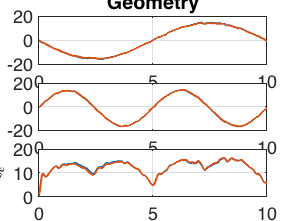

yiRec = V(xi,uiInt);
zi = yi(outdofsNew,:); ziRec = yiRec(outdofsNew,:); 

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title ('Geometry')
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',2);
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, ziRec(iObs, :),'Linewidth',2);
end

Check dynamics

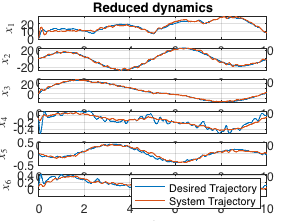

uFun = @(t) transpose(interp1(ti, transpose(ui), t));
[tiPred,xiPred] = ode45(@(t,x) R(t,x,uFun(t)),ti,xi(:,1)); 
tiPred = transpose(tiPred); xiPred = transpose(xiPred); 

% Plot time series
customFigure('subPlot',[6 1]);
labelsRD = {'$x_1$', '$x_2$', '$x_3$', '$x_4$', '$x_5$', '$x_6$'};
subplot(6,1,1); title ('Reduced dynamics')
for iPlt = 1:6
    subplot(6,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsRD(iPlt),'Interpreter','latex');
end
for iObs = 1:6
    subplot(6,1,iObs);
    plot(ti, xi(iObs, :),'Linewidth',1);
end
for iObs = 1:6
    subplot(6,1,iObs);
    plot(tiPred, xiPred(iObs, :),'Linewidth',1);
end
legend('Desired Trajectory', 'System Trajectory');

Check overall reduced-order model

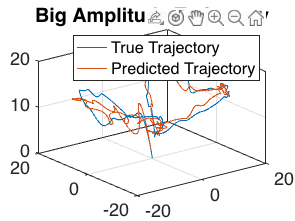

nStepsPred = length(tiPred);
if nStepsPred<length(ti)
   tiPred(nStepsPred+1:length(ti)) = NaN; xiPred(:,nStepsPred+1:length(ti)) = NaN; 
end
yiPred = V(xiPred,uiInt);
zi = yi(outdofsNew,:); ziPred = yiPred(outdofsNew,:);

% Visualize the trajectory in 3d
customFigure; 
plot3(zi(1, :), zi(2, :), zi(3, :),'Linewidth',1);
plot3(ziPred(1, :), ziPred(2, :), ziPred(3, :),'Linewidth',1);
legend('True Trajectory', 'Predicted Trajectory');
title('Big Amplitude Trajectory');
view(3);


RMSE = sum(sqrt(mean((ziPred(1:3, :) - zi).^2))) / size(ziPred, 2)

RMSE = 0.9591

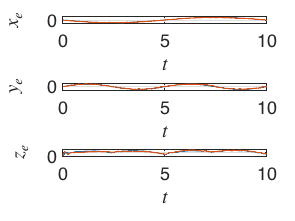


% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(tiPred, ziPred(iObs, :),'Linewidth',1);
end

**Validate short time Control model**

Nhoriz = 100;
etaData = Yu;
for iTraj=1:size(etaData, 1)
    etaData{iTraj,2} = IMInfo.chart.map(Yu{iTraj,2});
end
nEval = length(etaData{1,1})-Nhoriz;
yDataPredHoriz = cell(1,5);
iRow = 1;
for iTime = 1:nEval
    uHoriz = Udelay{iTraj,2}(:,iTime:iTime+Nhoriz);
    tHoriz = Udelay{iTraj,1}(iTime:iTime+Nhoriz);
    uFun = @(t) transpose(interp1(tHoriz, transpose(uHoriz), t));
    [iTimeRec, ietaRec] = ode15s(@(t,x) R(t,x,uFun(t)),tHoriz,etaData{1,2}(:,iTime));
    % Lift
    iyRec = liftTrajectories(IMInfo, {iTimeRec, transpose(ietaRec)});
    
    yDataPredHoriz{iRow,1} = etaData{iTraj,1}(iTime:iTime+Nhoriz);
    yDataPredHoriz{iRow,2} = ietaRec(:,:);
    yDataPredHoriz{iRow,3} = etaData{iTraj,1}(iTime+Nhoriz);
    yDataPredHoriz{iRow,4} = iyRec{1,2}(outdofsNew,:);
    yDataPredHoriz{iRow,5} = iTime;
    iRow = iRow + 1;
end

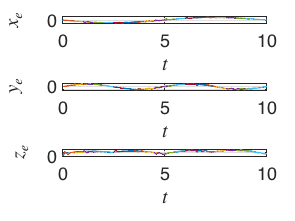

tTrue = t_span(1:end-1); 
zTrue = zi;

% Plot time series
idxPlotCL = 50;
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zTrue(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    for iTraj=1:idxPlotCL:size(yDataPredHoriz,1)
        plot(yDataPredHoriz{iTraj,1}, yDataPredHoriz{iTraj,4}(iObs,:),'Linewidth',1);
    end
end

## Export mapping coefficients and input matrix

% Continuous-time model
Ts = 0.01;
% TODO: Save either known input matrix or learned input matrix
% B_r = [zeros(rdof,size(Hred,2)); Hred];
B_r = Br;
w_coeff = IMInfo.parametrization.H; % reduced to observed
v_coeff = IMInfo.chart.H; % observed to reduced
r_coeff = RDInfo.reducedDynamics.coefficients;
Vde = [];
delays = 1;

py_data = struct();
ssm_model = struct();

ssm_model.w_coeff = w_coeff;
ssm_model.v_coeff = v_coeff;
ssm_model.r_coeff = r_coeff;
ssm_model.B = B_r;
ssm_model.V = Vde;

ssm_model.Ts = Ts;
py_data.model = ssm_model;

params = struct();
params.SSM_order = SSMOrder;
params.ROM_order = ROMOrder;
params.state_dim = 2*rdof;
params.input_dim = size(B_r, 2);
params.output_dim = odof;
params.delays = delays;
params.obs_dim = 2*odof; % For testing new functionality
py_data.params = params;

save('SSM_model_1delay.mat', 'py_data', '-v7')

